clear
warning('off')

% This will read the .c3d and .xls files. 
% The landmark positions are read from the .c3d file. The first frame is T-Pose.
% The joint positions are read from the .xls file and transferred to the origin.
% Finally, this plot height-landmark position.

% Data created by Xsens MVN 2021.2.0
% Instead of using the sensors to measure actual motion, we put the sensors still on the table. 
% We recorded several data with different heights(150-190cm). This does not affect scaling and T-Pose data generation.
c3dFileList = dir("Data\XsensData\XsensStatic_c3d\");
c3dFileList(1:2,:) = [];
xlsFileList = dir("Data\XsensData\XsensStatic_xls\");
xlsFileList(1:2,:) = [];

MarkArray = [];
MarkArray_G = [];
JointArray_G = [];

%Height 150-190cm
for i = 1:5
    c3dFileName = [c3dFileList(i).folder,'\',c3dFileList(i).name];
    %btk download from http://biomechanical-toolkit.github.io/docs/Wrapping/Matlab/index.html
    acq = btkReadAcquisition(c3dFileName);
    markers = btkGetMarkers(acq);
    hipOrigin = roundn(markers.pHipOrigin(1,:),-1);
    REFM_G = markers.pRightKneeMedEpicondyle(1,:);
    REFL_G = markers.pRightKneeLatEpicondyle(1,:);
    RMM_G = markers.pRightMedMalleolus(1,:);
    RLM_G = markers.pRightLatMalleolus(1,:);
    Height = markers.pTopOfHead(1,3);
    Height = round(Height);   

    xlsFileName = [xlsFileList(i).folder,'\',xlsFileList(i).name];
    SegPos = readtable(xlsFileName,"Sheet","Segment Position");
    SegQuat = readtable(xlsFileName,"Sheet","Segment Orientation - Quat"); 
    PelvisPos = roundn(SegPos{1,["PelvisX","PelvisY","PelvisZ"]}.*1000,-1);
    RHipJointPos = roundn(SegPos{1,["RightUpperLegX","RightUpperLegY","RightUpperLegZ"]}.*1000,-1);
    RKneeJointPos = roundn(SegPos{1,["RightLowerLegX","RightLowerLegY","RightLowerLegZ"]}.*1000,-1)
    RAnkleJointPos = roundn(SegPos{1,["RightFootX","RightFootY","RightFootZ"]}.*1000,-1)

    PelvisPos_G = [0,0,PelvisPos(3)];
    RHipJointPos_G =  RHipJointPos-[PelvisPos(1),PelvisPos(2),0];
    RKneeJointPos_G = (REFM_G+REFL_G)/2;
    RAnkleJointPos_G = (RMM_G+RLM_G)/2;

    xsensData = Data;
    xsensData.REFM = REFM_G;
    xsensData.REFL = REFL_G;
    xsensData.RMM = RMM_G;
    xsensData.RLM = RLM_G;    
    xsensData.RHipCenter = RHipJointPos_G;
    xsensData.RKneeCenter = (REFM_G+REFL_G)/2;
    xsensData.RAnkleCenter = (RMM_G+RLM_G)/2;

    
    xsensData.getFemoralOrientation;
    xsensData.getTibiaOrientationXsens;
    xsensData.getMarkPositionInSegment;
    
    REFM = xsensData.REFMInit;
    REFL = xsensData.REFLInit;
    RMM = xsensData.RMMInit;
    RLM = xsensData.RLMInit;


    MarkArray(i,:) = [i,REFM,REFL,RMM,RLM,Height];
    MarkArray_G(i,:) = [i,REFM_G,REFL_G,RMM_G,RLM_G,Height];
    JointArray_G(i,:) = [i,PelvisPos_G,RHipJointPos_G,RKneeJointPos_G,RAnkleJointPos_G,Height];     

end

RKneeJointPos =    82.0000    2.6000  429.9000


RAnkleJointPos =    53.1000    2.1000   70.7000


RKneeJointPos =    81.0000   -1.9000  457.4000


RAnkleJointPos =    50.3000   -2.5000   75.4000


RKneeJointPos =    80.1000   -6.4000  484.9000


RAnkleJointPos =    47.5000   -7.1000   80.0000


RKneeJointPos =    79.1000  -11.0000  512.5000


RAnkleJointPos =    44.6000  -11.6000   84.6000


RKneeJointPos =    78.1000  -15.5000  540.0000


RAnkleJointPos =    41.8000  -16.2000   89.2000




MarkTableXsens = array2table(MarkArray);
MarkTableXsens.Properties.VariableNames = {'SubjectID',...
    'REFMX','REFMY','REFMZ',...
    'REFLX','REFLY','REFLZ',...
    'RMMX','RMMY','RMMZ',...
    'RLMX','RLMY','RLMZ',...
    'Height(cm)'}

MarkTableXsens = 5×14 table
    SubjectID       REFMX        REFMY      REFMZ        REFLX        REFLY     REFLZ        RMMX         RMMY       RMMZ         RLMX         RLMY       RLMZ     Height(cm)
    _________    ___________    _______    _______    ___________    _______    ______    ___________    _______    _______    ___________    _______    ______    __________

        1         3.5527e-15    -370.84    -33.397     3.5527e-15    -371.23    33.397              0    -360.04    -28.851              0    -359.71    24.398       1500   
        2         7.1054e-15    -393.75    -35.446     7.1054e-15    -394.17    35.446     3.5527e-15    -382.96    -30.697     3.5527e-15    -382.61    25.947       1600   
        3        -3.5527e-15    -416.64    -37.499    -3.5527e-15    -417.08    37.499              0    -405.96    -32.507              0    -405.59    27.514       1700   
        4                  0     -439.5    -39.536              0    -439.97    39.536    -3.5527e-15


MarkTableXsens_G = array2table(MarkArray_G);
MarkTableXsens_G.Properties.VariableNames = {'SubjectID',...
    'REFMX','REFMY','REFMZ',...
    'REFLX','REFLY','REFLZ',...
    'RMMX','RMMY','RMMZ',...
    'RLMX','RLMY','RLMZ',...
    'Height(cm)'}

MarkTableXsens_G = 5×14 table
    SubjectID     REFMX      REFMY     REFMZ      REFLX      REFLY     REFLZ      RMMX       RMMY       RMMZ      RLMX       RLMY       RLMZ     Height(cm)
    _________    _______    _______    ______    _______    _______    ______    _______    _______    ______    _______    _______    ______    __________

        1        -24.046    -39.796    429.88    -24.046    -106.59    429.88    -46.874    -44.342    70.732    -46.874    -97.591    70.732       1500   
        2        -25.497    -42.396     457.4    -25.497    -113.29     457.4    -49.795    -47.145    75.392    -49.795    -103.79    75.392       1600   
        3        -26.983    -44.989    484.95    -26.983    -119.99    484.95    -52.691    -49.982    79.992    -52.691       -110    79.992       1700   
        4        -28.458    -47.579    512.52    -28.458    -126.65    512.52    -55.622     -52.81    84.698    -55.622    -116.19    84.698       1800   
        5         -29.92    -50.1


JointTableXsensArray_G = array2table(JointArray_G);
JointTableXsensArray_G.Properties.VariableNames = {'SubjectID',...
    'PelvisX','PelvisY','PelvisZ',...
    'RHipJointX','RHipJointY','RHipJointZ',...
    'RKneeJointX','RKneeJointY','RKneeJointZ',...
    'RAnkleJointX','RAnkleJointY','RAnkleJointZ',...
    'Height(cm)'}

JointTableXsensArray_G = 5×14 table
    SubjectID    PelvisX    PelvisY    PelvisZ    RHipJointX    RHipJointY    RHipJointZ    RKneeJointX    RKneeJointY    RKneeJointZ    RAnkleJointX    RAnkleJointY    RAnkleJointZ    Height(cm)
    _________    _______    _______    _______    __________    __________    __________    ___________    ___________    ___________    ____________    ____________    ____________    __________

        1           0          0        799.9        0.4            -71          800.1        -24.046        -73.193        429.88         -46.874         -70.967          70.732          1500   
        2           0          0        850.4        0.4          -75.5          850.5        -25.497        -77.842         457.4         -49.795         -75.467          75.392          1600   
        3           0          0        900.9        0.4            -80          900.9        -26.983        -82.489        484.95         -52.691         -79.992          79.992 

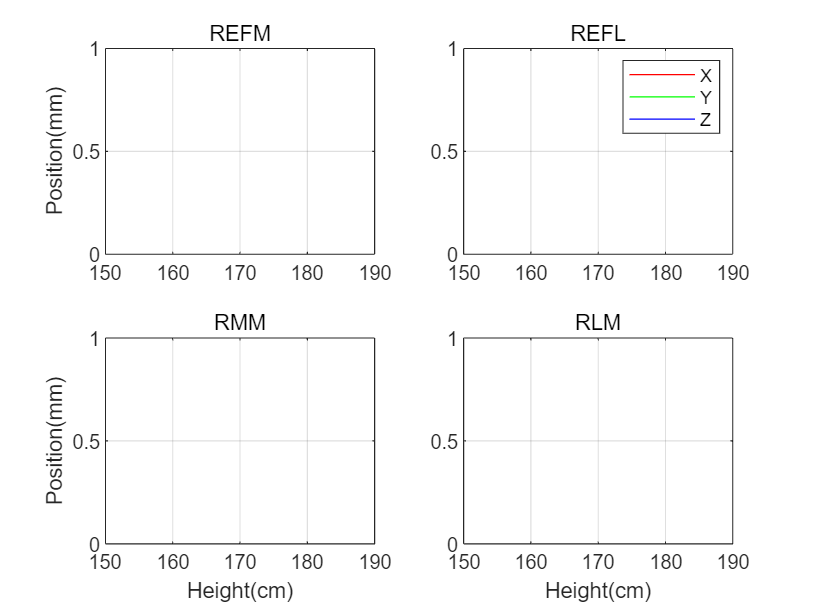


save("Data\Regression\MarkTableXsens.mat",'MarkTableXsens')


figure
subplot(2,2,1);hold on;title("REFM");xlim([150,190]);box on;grid on
ylabel('Position(mm)')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFMX,'r')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFMY,'g')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFMZ,'b')

subplot(2,2,2);hold on;title("REFL");xlim([150,190]);box on;grid on
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFLX,'r')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFLY,'g')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFLZ,'b')
legend({'X','Y','Z'})

subplot(2,2,3);hold on;title("RMM");xlim([150,190]);box on;grid on
ylabel('Position(mm)');xlabel('Height(cm)')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RMMX,'r')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RMMY,'g')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RMMZ,'b')

subplot(2,2,4);hold on;title("RLM");xlim([150,190]);box on;grid on
xlabel('Height(cm)')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RLMX,'r')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RLMY,'g')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RLMZ,'b')